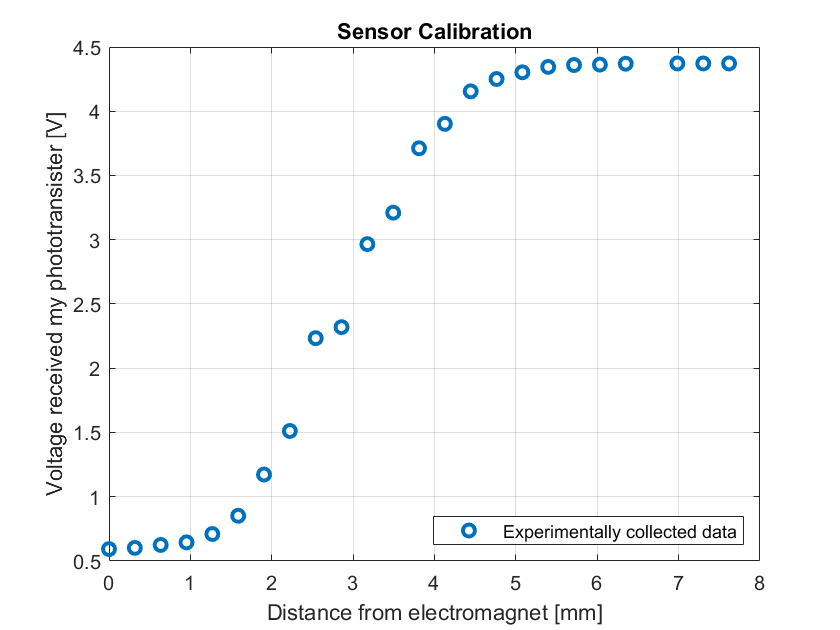

% Every quater rotation between 0mm to 12.7mm
clear all ; close all;
[Cali] = xlsread("Calibration.xlsx");

x_mm = Cali(1:end, 3);
e_input = Cali(1:end, 4);

figure(1);hold on; grid on; box on;
plot(x_mm,e_input,'o','LineWidth',2);
title("Sensor Calibration");
xlabel("Distance from electromagnet [mm]");
ylabel("Voltage received my phototransister [V]")
legend('Experimentally collected data','Location',"southeast")

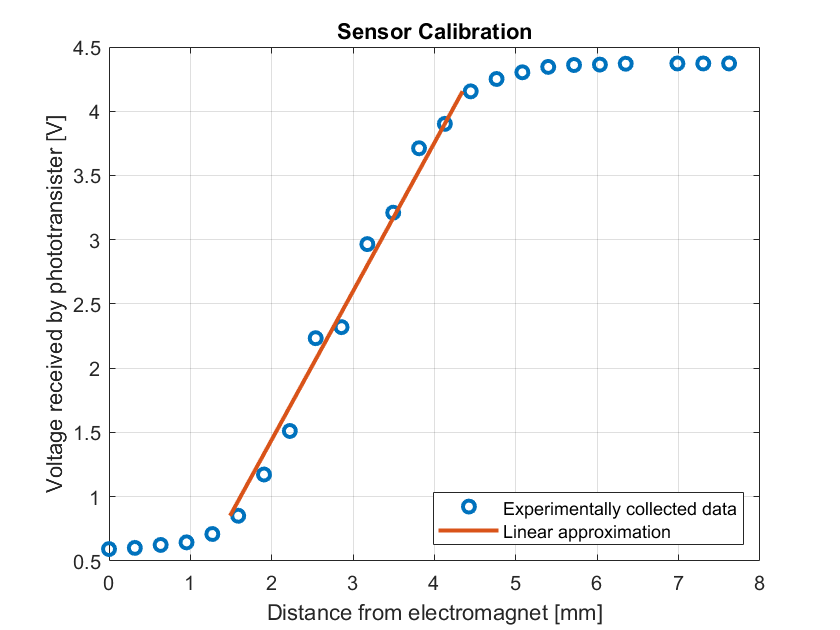

% Considering Linear behavior between points (1.5875,0.852) & (4.445,4.155)

x = [1.4875 4.345];
y = [0.852 4.155];

figure(2);hold on; grid on; box on;
plot(x_mm,e_input,'o','LineWidth',2);
plot(x,y,'LineWidth',2);
title("Sensor Calibration");
xlabel("Distance from electromagnet [mm]");
ylabel("Voltage received by phototransister [V]")
legend('Experimentally collected data','Linear approximation','Location',"southeast")

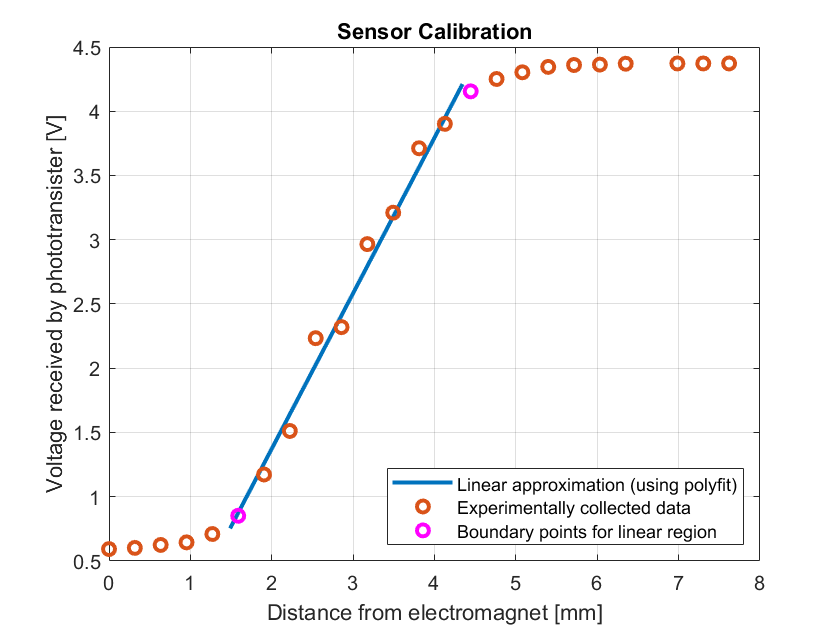


% Polyfit
x_mm_f = Cali(6:15, 3);
e_input_f = Cali(6:15, 4);
figure(3);hold on; grid on; box on;
P = polyfit(x_mm_f,e_input_f,1);
yfit = P(1)*x+P(2);
plot(x,yfit,"LineWidth",2);
plot(x_mm,e_input,'o','LineWidth',2);
plot(Cali(6,3),Cali(6,4),'mo','LineWidth',2);
plot(Cali(15,3),Cali(15,4),'mo','LineWidth',2);
title("Sensor Calibration");
xlabel("Distance from electromagnet [mm]");
ylabel("Voltage received by phototransister [V]")
legend('Linear approximation (using polyfit)','Experimentally collected data','Boundary points for linear region','Location',"southeast")

P(1)

ans = 1.2103